# Example 7.9: Two-Stage Formulation for Generator Sizing

Note: this script reproduces Example 7.9 (Section 7.6.3) of **Statistics for Chemical Engineers**: sizing a flexible generator for two random loads, with deterministic and two-stage stochastic formulations. Victor Z UW-Madison, 2022 generator sizing example (two-stage formulation)

clc; clear all; close all hidden; format short;

## Load scenarios

generate scenarios for random load

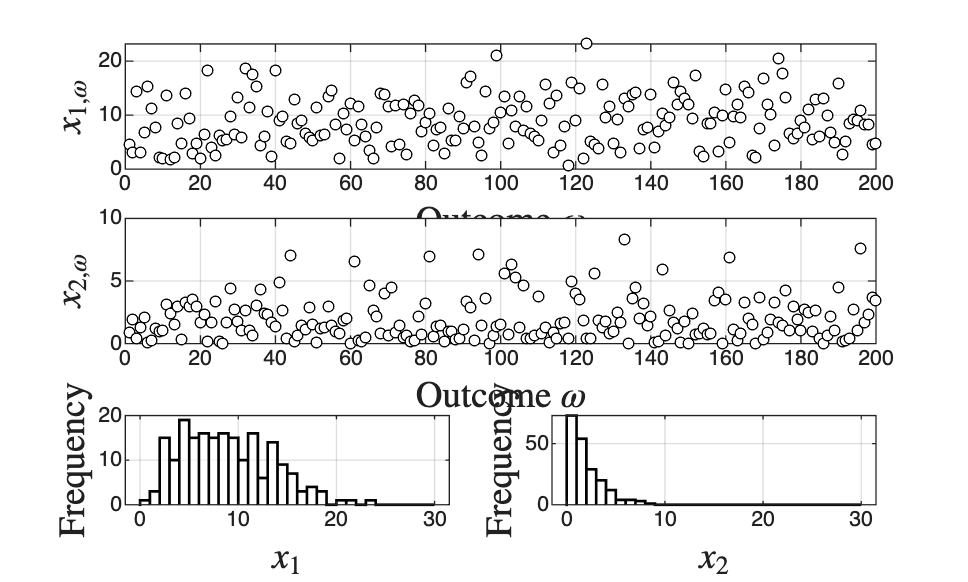

rng(0)
N=200;
X1=wblrnd(10,2,N,1);
X2=wblrnd(2,1,N,1);

figure(1)
subplot(3,2,[1 2])
plot(X1,'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('Outcome $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_{1,\omega}$','Interpreter','latex','FontSize',14)
grid on
subplot(3,2,[3 4])
plot(X2,'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('Outcome $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_{2,\omega}$','Interpreter','latex','FontSize',14)
grid on
subplot(3,2,5)
histogram(X1,0:1:30,'Normalization','count','EdgeColor','black','FaceColor','white','LineWidth',1)
grid on
hold on
xlabel('$x_1$','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Frequency}$','Interpreter','latex','FontSize',14)
subplot(3,2,6)
histogram(X2,0:1:30,'Normalization','count','EdgeColor','black','FaceColor','white','LineWidth',1)
grid on
hold on
xlabel('$x_2$','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Frequency}$','Interpreter','latex','FontSize',14)
print -depsc -r1200 ch7_generator_twostage_data.eps


opt = optimoptions('fmincon','Display','none','Algorithm','sqp');

## Deterministic solution

find deterministic solution

u=[1,10];
for k=1:length(u)
    
data.X1 = max(X1);
data.X2 = max(X2);

data.u = u(k);
    W0 = zeros(1,1);
     W = fmincon(@myfundet,W0,[],[],[],[],[],[],@mycon,opt,data);
rho(k) = myfundet(W,data);

end

idx=find(rho==min(rho));
udet=u(idx)

udet = 10


% evaluate performance
data.X1=X1;
data.X2=X2;
data.u=udet;
    W0 = zeros(N,1);
  Wdet = fmincon(@myfun,W0,[],[],[],[],[],[],@mycon,opt,data);
rhodet = myfun(Wdet,data)

rhodet = 1.9964e+03

## Two-stage stochastic solution

find stochastic solution

for k=1:length(u)
    
data.X1=X1;
data.X2=X2;
data.u=u(k);
    W0 = zeros(N,1);
     W = fmincon(@myfun,W0,[],[],[],[],[],[],@mycon,opt,data);
rho(k) = myfun(W,data);

end
 
idx=find(rho==min(rho));
ustoch=u(idx)

ustoch = 1


% evaluate performance
data.X1=X1;
data.X2=X2;
data.u=ustoch;
      W0 = zeros(N,1);
  Wstoch = fmincon(@myfun,W0,[],[],[],[],[],[],@mycon,opt,data);
rhostoch = myfun(Wstoch,data)

rhostoch = 1.8021e+03

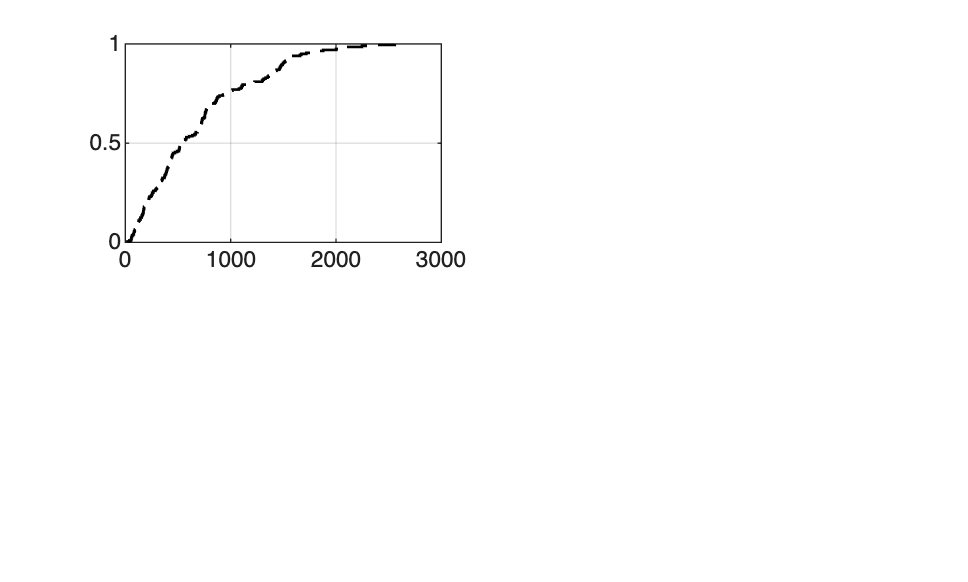


ystoch = costfun(Wstoch,data);

figure(2)
subplot(2,2,1)
[F,t]=ecdf(ystoch);
stairs(t,F,'LineWidth',1,'Color','black','LineStyle','--')
grid on
hold on

## definition of functions

% risk measure 
function rho = myfun(W,data)
 
    u=data.u;
    X1=data.X1;
    X2=data.X2;

   R = X1+X2-W;
   y = 5*(R.^2) + 15*u.^2;

   Q = quantile(y,0.9);
 loc = y >= Q;
 rho = mean(y(loc));
 
end

% cost
function y = costfun(W,data)
 
    u=data.u;
    X1=data.X1;
    X2=data.X2;

   R = X1+X2-W;
   y = 5*(R.^2) + 15*u.^2;
 
end

% objective det
function rho = myfundet(W,data)
 
    u=data.u;
    X1=data.X1;
    X2=data.X2;

     R = X1+X2-W;
     y = 5*(R.^2) + 15*u.^2;
   rho = y;
 
end

% constraint
function [con,ceq] = mycon(W,data)
 
u=data.u;
X1=data.X1;
X2=data.X2;

con = W-X1-X2;
con = [con; W-u];
con = [con; -W];

ceq = [];

end

## Note

As in the book, the deterministic solution depends on how we choose representative values of the loads, which is not obvious when many RVs are present; the stochastic formulation avoids this.